# SIP LAB-2 Prac

## SUM

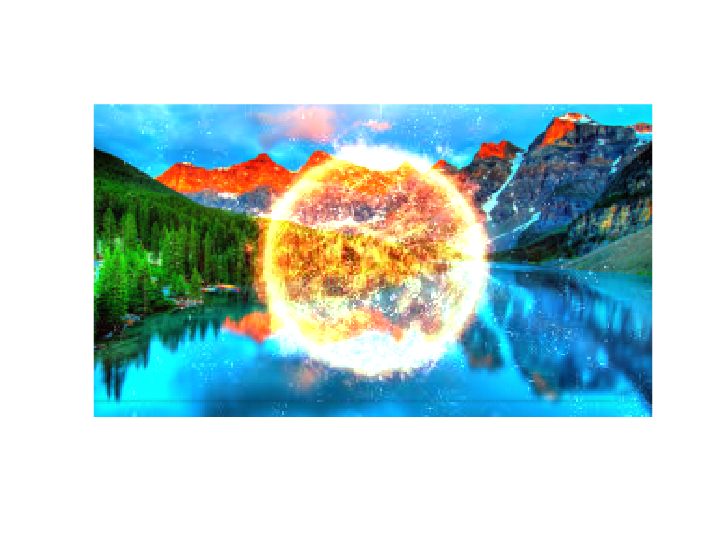

clc;clf;clear all;
a=imread('img1.jpg');
b=imread('img2.jpg');
c=imresize(b,[168,300]);
sum=imadd(a,c);
imshow(sum)

## Sub

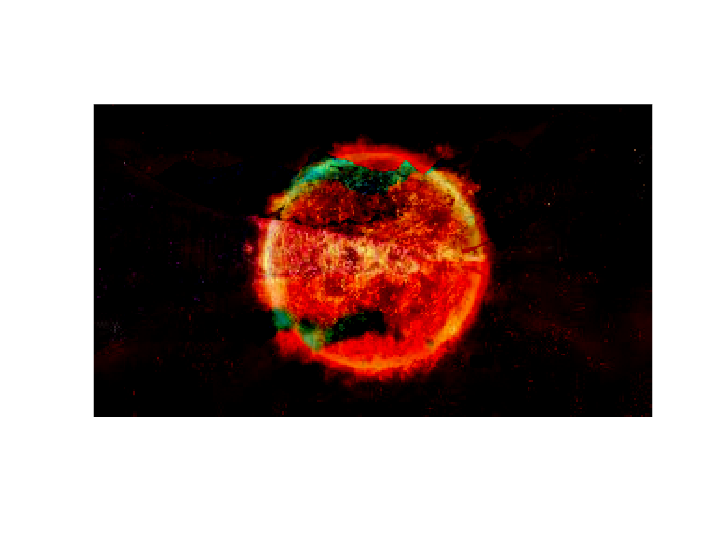

sub=imsubtract(a,c);
imshow(sub)

## Histogram plotting

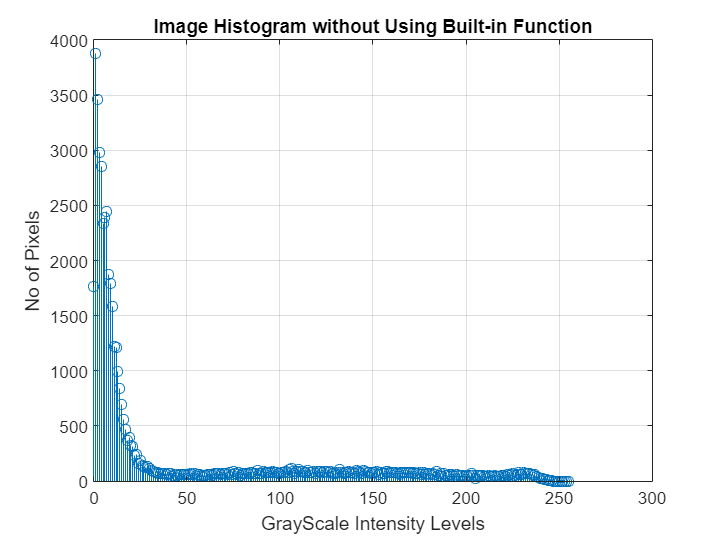

d=imread('img1.jpg');
Gray_Image=rgb2gray(d);
img_hist=zeros(1,256);
[e,f]=size(Gray_Image);
x=e;y=f;
for i=1:x
    for j=1:y
       img_hist(Gray_Image(i,j,1)+1) = img_hist(Gray_Image(i,j,1)+1)+1;
    end
end
stem(0:255, img_hist); 
grid on;
ylabel('No of Pixels');
xlabel('GrayScale Intensity Levels'); 
title('Image Histogram without Using Built-in Function');

## Histogram processing

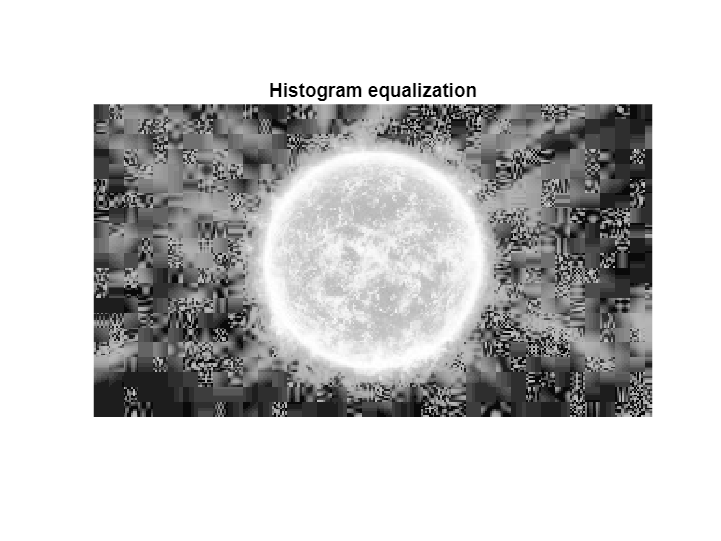

GIm=Gray_Image;
numofpixels=size(GIm,1)*size(GIm,2);
HIm=uint8(zeros(size(GIm,1),size(GIm,2)));
freq=zeros(256,1);
probf=zeros(256,1);
probc=zeros(256,1);
cum=zeros(256,1);
output=zeros(256,1);
%freq counts the occurrence of each pixel value.
%The probability of each occurrence is calculated by probf.
for i=1:size(GIm,1)
 for j=1:size(GIm,2)
 value=GIm(i,j);
 freq(value+1)=freq(value+1)+1;
 probf(value+1)=freq(value+1)/numofpixels;
 end
end
sum=0;
no_bins=255;
%The cumulative distribution probability is calculated. 
for i=1:size(probf)
 sum=sum+freq(i);
 cum(i)=sum;
 probc(i)=cum(i)/numofpixels;
 output(i)=round(probc(i)*no_bins);
end
for i=1:size(GIm,1)
 for j=1:size(GIm,2)
 HIm(i,j)=output(GIm(i,j)+1);
 end
end
imshow(HIm);
title('Histogram equalization');

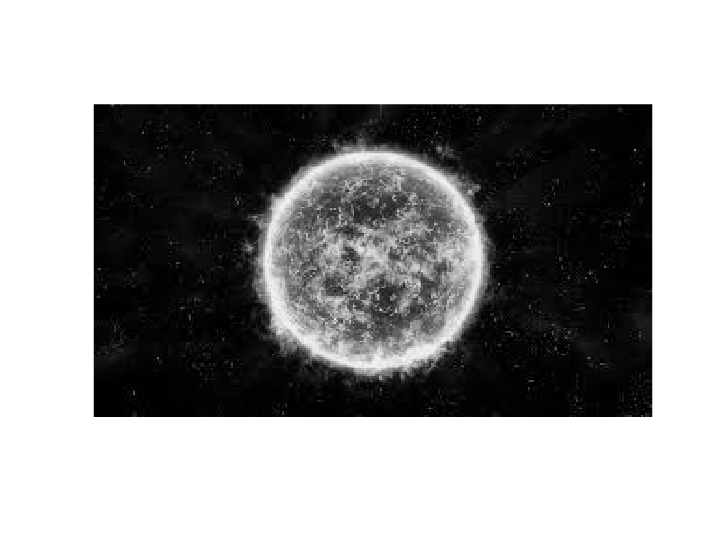

imshow(Gray_Image)

J=histeq(Gray_Image)

J = 168×300 uint8 matrix
    36    36    36    53    53    69    69    69    36   190   202   142    53    36   186   162   125   125   125   125   125   125   125   125   117   105   105    93    81    69    53    53    69   105   134   150   142   105    53    36    81    81    81    81    81    81    81    81    16     8
    36    36    36    53    53    69    69    69   142   166   182   134   125    36   117   105   125   125   125   125   125   125   125   125   117   117   105    93    81    69    69    53    69    93   105   125   125   117    93    81    93    93    93    93    93    93    93    93    16     8
    36    36    36    53    53    69    69    69   166    36    36   142   150    53    36    93   134   134   134   134   134   134   134   134   125   117   117   105    93    81    69    69    81    69    69    69    93   125   150   158    93    93    93    93    93    93    93    93    16    36
    36    36    36    53    53    69    69    69    93    53    53   150

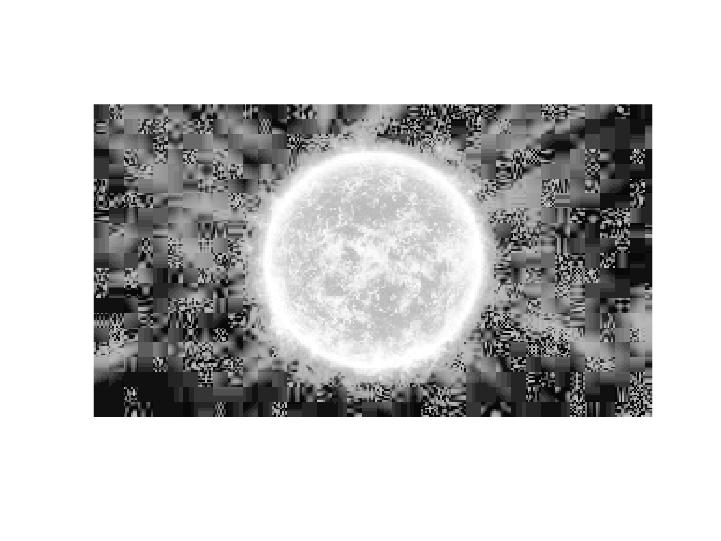

imshow(J)

## Thresholding

clc;
x=imread('img1.jpg');
x=rgb2gray(x);
x=double(x);
tot=0;
[a,b]=size(x);
y=zeros(a,b);
for i=1:a
 for j=1:b
 y(i,j)=0;
 end
end
for i=1:a
 for j=1:b
 tot=tot+x(i,j);
 end
end
tot

tot = 2132143

c= a*b

c = 50400

thr=tot/(a*b)

thr = 42.3044

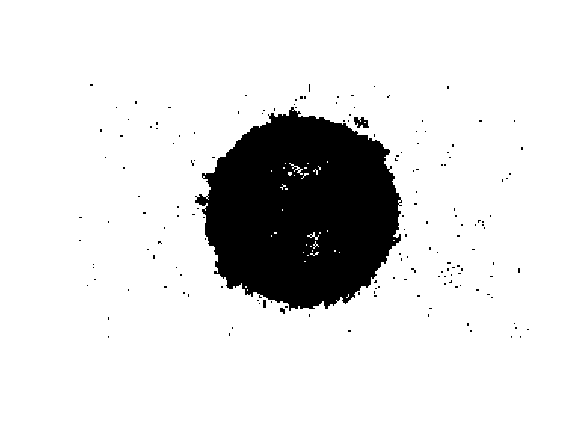

for i=1:a
 for j=1:b
 if x(i,j) > thr
 y(i,j)=0;
 else
 y(i,j)=1;
 end
 end
end
figure;
imshow(y);

## contrast streaching

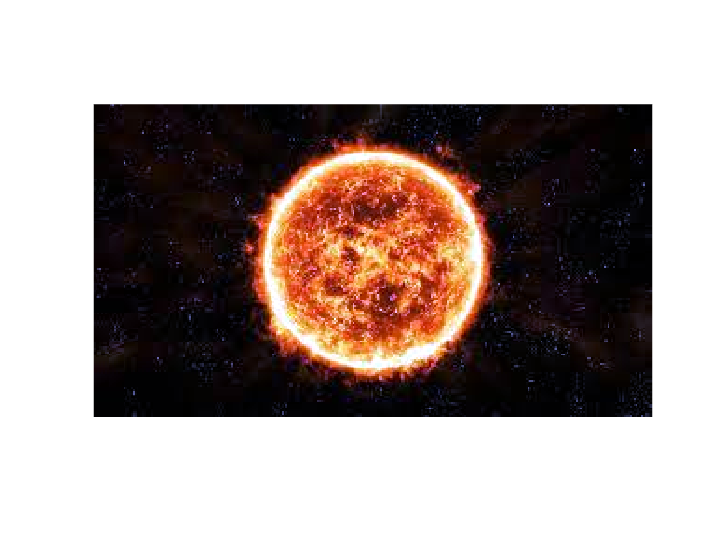

stretched_Image = imadjust(imread('img1.jpg'), stretchlim(imread('img1.jpg'),[0.01 0.99]),[]);
imshow(stretched_Image)

## 2D Transformations

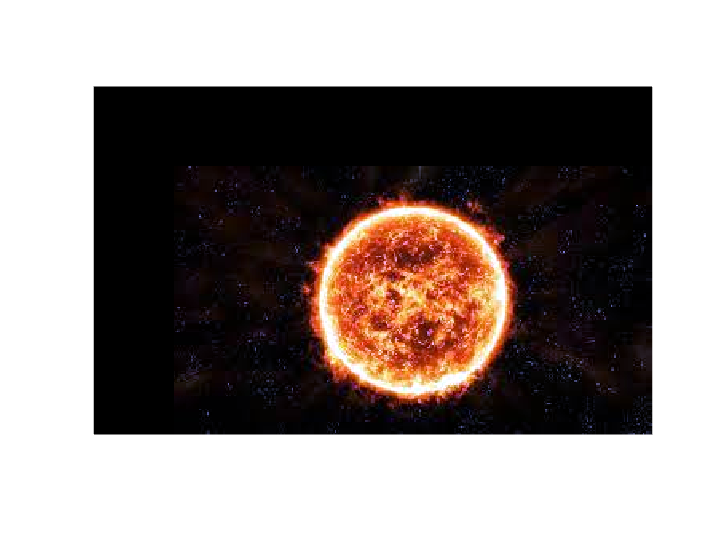

stretched_Image1=uint8(zeros(size(stretched_Image,1)+2,size(stretched_Image,2)+2,3));
transx=50;
transy=50;
for i=1:size(stretched_Image,1)
 for j=1:size(stretched_Image,2)
 for k=1:3
 stretched_Image1(i+transx,j+transy,k)=stretched_Image(i,j,k);
 end 
 end
end
imshow(stretched_Image1)

theta=0;
tform=rigid2d([cosd(theta) sind(theta);-sind(theta) cosd(theta)],[transx,transy])

tform =   rigid2d with properties:

       Rotation: [2×2 double]
    Translation: [50 50]


img2_ref=imref2d(size(stretched_Image))

img2_ref =   imref2d with properties:

           XWorldLimits: [0.5000 300.5000]
           YWorldLimits: [0.5000 168.5000]
              ImageSize: [168 300]
    PixelExtentInWorldX: 1
    PixelExtentInWorldY: 1
    ImageExtentInWorldX: 300
    ImageExtentInWorldY: 168
       XIntrinsicLimits: [0.5000 300.5000]
       YIntrinsicLimits: [0.5000 168.5000]


img2_ref.XWorldLimits(2)=img2_ref.XWorldLimits(2)+100

img2_ref =   imref2d with properties:

           XWorldLimits: [0.5000 400.5000]
           YWorldLimits: [0.5000 168.5000]
              ImageSize: [168 300]
    PixelExtentInWorldX: 1.3333
    PixelExtentInWorldY: 1
    ImageExtentInWorldX: 400
    ImageExtentInWorldY: 168
       XIntrinsicLimits: [0.5000 300.5000]
       YIntrinsicLimits: [0.5000 168.5000]


img2_ref.YWorldLimits(2)=img2_ref.YWorldLimits(2)+100

img2_ref =   imref2d with properties:

           XWorldLimits: [0.5000 400.5000]
           YWorldLimits: [0.5000 268.5000]
              ImageSize: [168 300]
    PixelExtentInWorldX: 1.3333
    PixelExtentInWorldY: 1.5952
    ImageExtentInWorldX: 400
    ImageExtentInWorldY: 268
       XIntrinsicLimits: [0.5000 300.5000]
       YIntrinsicLimits: [0.5000 168.5000]


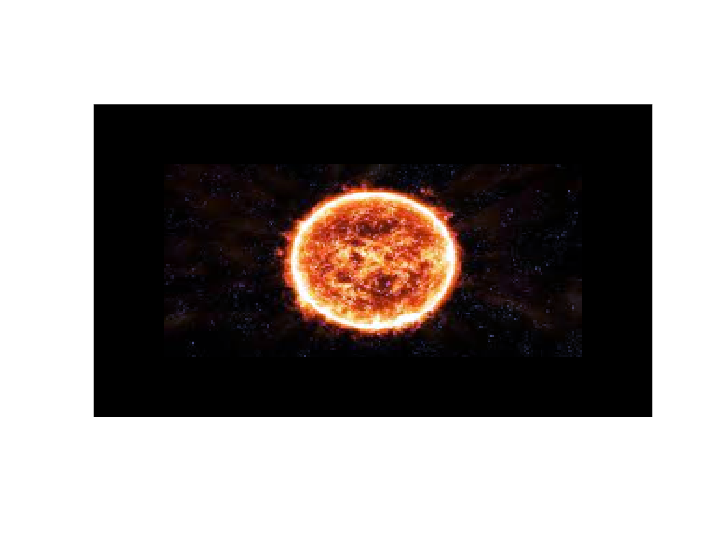

imshow(imwarp(stretched_Image,tform,"OutputView",img2_ref))

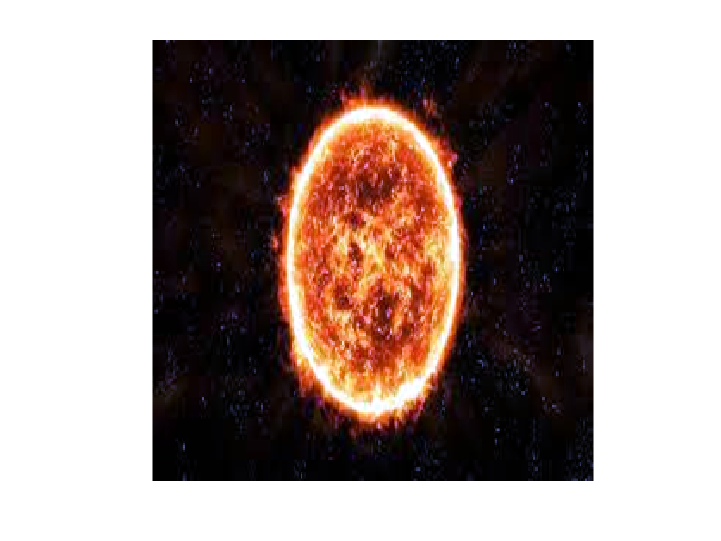

stretched_Image=imresize(stretched_Image,[256,256]);
imshow(stretched_Image)

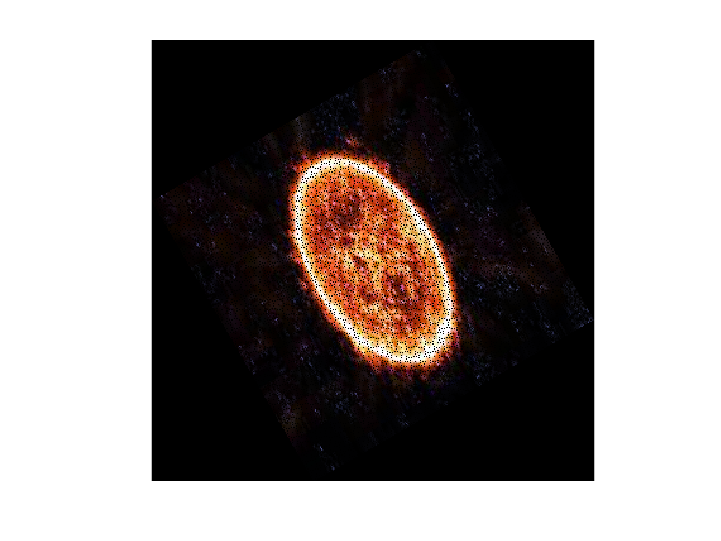

stretched_Image1=uint8(zeros(size(stretched_Image,1),size(stretched_Image,2),3));
theta=30;
for i=1:size(stretched_Image,1)
 for j=1:size(stretched_Image,2)
 for k=1:3
 stretched_Image1(round((i*cosd(theta)-j*sind(theta)+size(stretched_Image,2)*sind(theta))),round((i*sind(theta)+j*cosd(theta))),k)=stretched_Image(i,j,k);
 end 
 end
end
imshow(stretched_Image1)

theta=30;
tform=rigid2d([cosd(theta) sind(theta);-sind(theta) cosd(theta)],[0,0])

tform =   rigid2d with properties:

       Rotation: [2×2 double]
    Translation: [0 0]


img2_ref=imref2d(size(stretched_Image))

img2_ref =   imref2d with properties:

           XWorldLimits: [0.5000 256.5000]
           YWorldLimits: [0.5000 256.5000]
              ImageSize: [256 256]
    PixelExtentInWorldX: 1
    PixelExtentInWorldY: 1
    ImageExtentInWorldX: 256
    ImageExtentInWorldY: 256
       XIntrinsicLimits: [0.5000 256.5000]
       YIntrinsicLimits: [0.5000 256.5000]


img2_ref.XWorldLimits(1)=img2_ref.XWorldLimits(1)-size(stretched_Image,2)*sind(theta)

img2_ref =   imref2d with properties:

           XWorldLimits: [-127.5000 256.5000]
           YWorldLimits: [0.5000 256.5000]
              ImageSize: [256 256]
    PixelExtentInWorldX: 1.5000
    PixelExtentInWorldY: 1
    ImageExtentInWorldX: 384
    ImageExtentInWorldY: 256
       XIntrinsicLimits: [0.5000 256.5000]
       YIntrinsicLimits: [0.5000 256.5000]


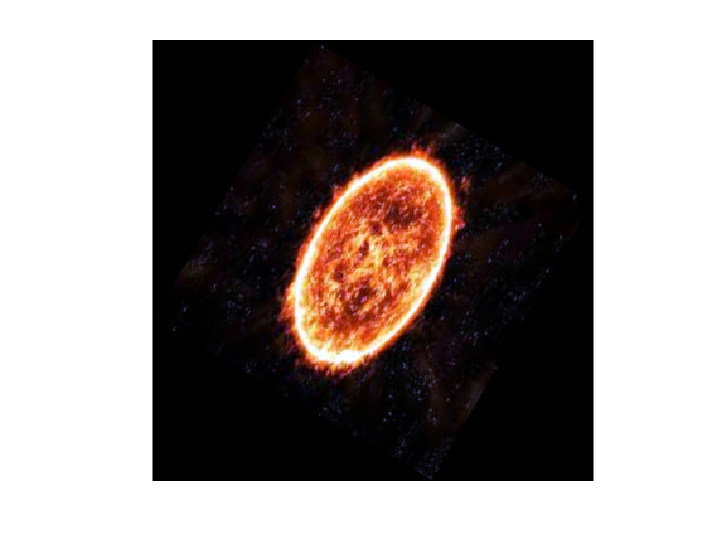

imshow(imwarp(stretched_Image,tform))

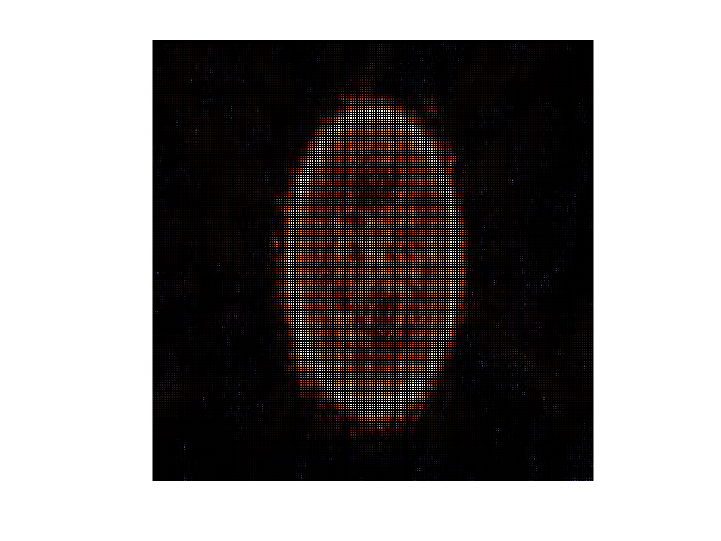

stretched_Image1=uint8(zeros(size(stretched_Image,1),size(stretched_Image,2),3));
theta=30;
for i=2:size(stretched_Image,1)
 for j=1:size(stretched_Image,2)
 for k=1:3
 stretched_Image1(i*2,j*2,k)=stretched_Image(i,j,k);
 end 
 end
end
imshow(stretched_Image1)

## Edge detection

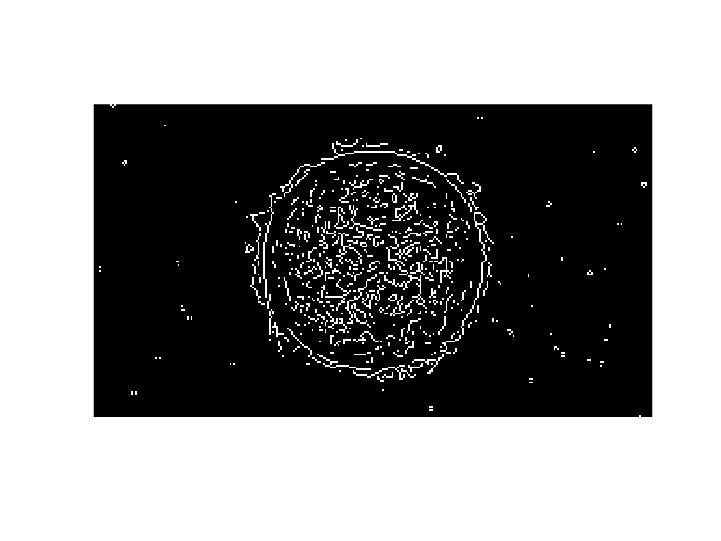

edgedetect = edge(Gray_Image,'sobel');
imshow(edgedetect)

## Smoothing the image

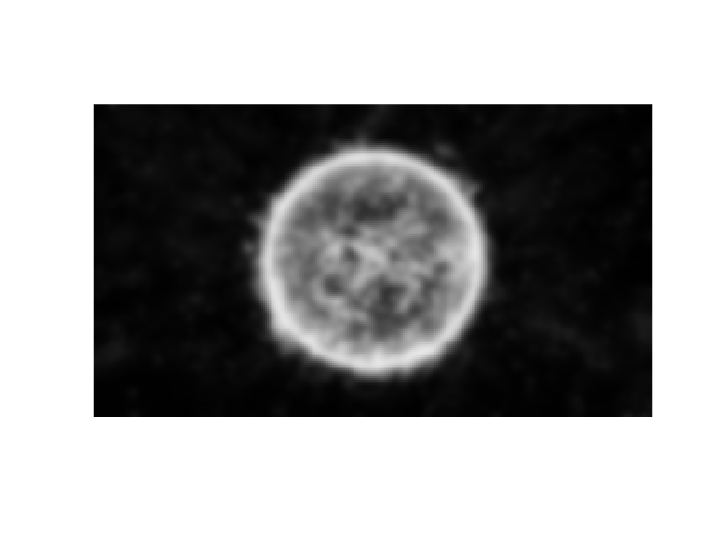

Imblur1 = imgaussfilt(Gray_Image,2);
Imblur2 = imgaussfilt(Gray_Image,6);8
imshow(Imblur1)

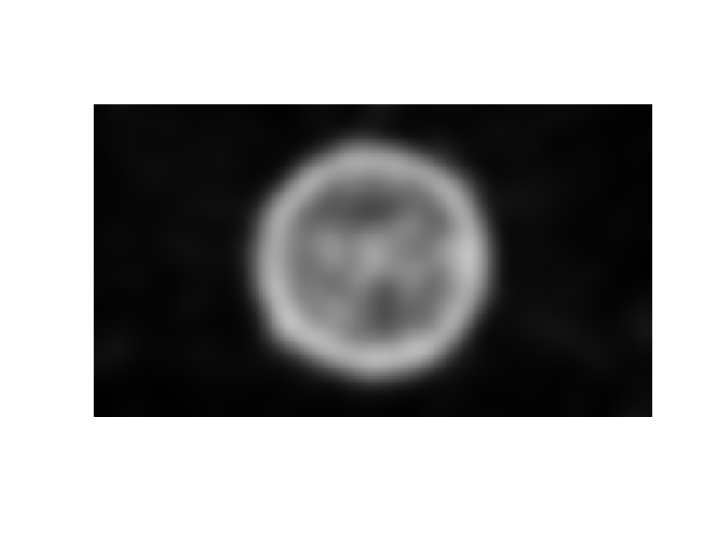

imshow(Imblur2)